# Obtener datos climáticos

## Importación del archivo de datos

%%% Descargar los datos de la página de AEMET en txt y abrirlo en un Excel
%%% Al importarlo, poner como separador el símbolo }
%%% Una vez importado, reemplazar los signos [ { que sobran por un espacio en blanco
%%% Reemplazar los signos consecutivos ", por " para tener un formato homogéneo
%%% Separar los datos por columnas utilizando como delimitadores el espacio
% junto con el signo : y marcar la casilla "Considerar separadores
% consecutivos como uno solo". Conseguiremos que se nos separen bien los
% datos. Eliminar la primera columna (vacía). Reemplazar las comas por
% puntos (separadores decimales). 

[file, path] = uigetfile('*.csv', 'Select a file', 'C:\Users\usuario\Desktop\Renate-files');
climate = importClimate([path, file]);

## Creación de tablas con los datos de interés

date = datetime(table2array(climate(climate.Col1 == "fecha", 2))); % Fecha
averageWindSpeed = double(table2array(climate(climate.Col1 == "velmedia", 2))); % Velocidad media del viento
maxWindSpeed = double(table2array(climate(climate.Col1 == "racha", 2))); % Velocidad máxima del viento
averageTemp = double(table2array(climate(climate.Col1 == "tmed", 2))); % Temperatura media
rain = double(table2array(climate(climate.Col1 == "prec", 2))); % Precipitación (mm)
minTemp = double(table2array(climate(climate.Col1 == "tmin", 2))); % Temperatura mínima
maxTemp = double(table2array(climate(climate.Col1 == "tmax", 2))); % Temperatura máxima
dirWind = double(table2array(climate(climate.Col1 == "dir", 2))); % Dirección del viento (decenas de grado)

## Creación de tabla única con las variables de interés

% Crear una tabla en blanco con el número de filas definidos por el número
% de fechas y número de variables que deseo tener 

sz = [1160 9];
varTypes = ["double" "datetime","double","double", "double", "double", "double", "double", "double"];
varNames = ["idxDate", "date","rain","avgWindSpeed", "maxWindSpeed", "dirWind","avgTemp", "maxTemp", "minTemp"];
fullTable = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames); 

% Contador para indexar las filas de la tabla vacía
k = 1;

wantedVars = ["prec","velmedia", "racha", "dir", "tmed", "tmax", "tmin"];
mirrorVars = ["rain","avgWindSpeed", "maxWindSpeed", "dirWind", "avgTemp", "maxTemp", "minTemp"];

% Bucle for 
for i=1:numel(climate.Col1) % Recorre todas las filas de los datos obtenidos de AEMET

    if climate.Col1(i) == "fecha" % Al encontrar la fila de fecha
        if i == 1 % Si es la primera fila, extraer la fecha y ponerla en la tabla vacía
        fullTable.date(k) = datetime(climate.Col2(i), 'InputFormat', 'dd/MM/uuuu'); 
        fullTable.idxDate(k) = i; 

        else % Si no es la primera fila, añadir 1 al contador de la tabla vacía,
                        % extraer la fecha y ponerla en la tabla vacía
        k = k + 1;
        fullTable.date(k) = datetime(climate.Col2(i), 'InputFormat', 'dd/MM/uuuu');
        fullTable.idxDate(k) = i; 
        end

    elseif any(ismember(wantedVars, climate.Col1(i))) && (i - fullTable.idxDate(k)) < 20 % Añadir otras variables a la tabla
        selectedVar = ismember(wantedVars, climate.Col1(i));
        fullTable{k, mirrorVars(selectedVar)} = str2double(climate.Col2(i));
    end
end

## Completar el formato de los datos

%% Hacer NaN los datos que son 0 (ausencia de datos en estas columnas)
fullTable.avgWindSpeed(fullTable.avgWindSpeed == 0) = NaN;
fullTable.maxWindSpeed(fullTable.maxWindSpeed == 0) = NaN;
fullTable.avgTemp(fullTable.avgTemp == 0) = NaN;
fullTable.maxTemp(fullTable.maxTemp == 0) = NaN;
fullTable.minTemp(fullTable.minTemp == 0) = NaN;

% Multiplicar la tabla de dirección de viento por 10 (para pasarlo de
% decenas de grado a grados)
fullTable.dirWind = fullTable.dirWind * 10;

% Especificar el formato de fecha para que se guarde bien en archivo
fullTable.date.Format = "dd/MM/uuuu";

## Representar

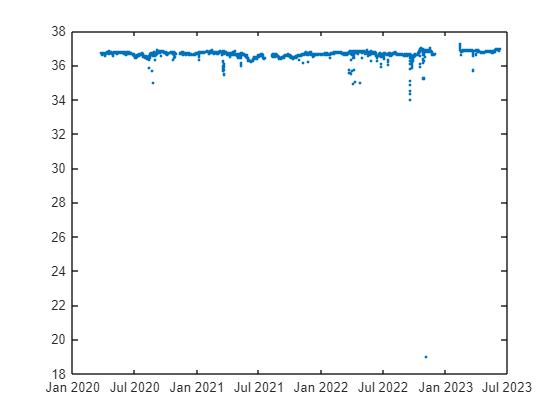

% Datos de viento de dirección variable
plot(fullTable.date(fullTable.dirWind ~= 99), fullTable.dirWind(fullTable.dirWind ~= 99), ".")

% Salinidad
plot(salinidadGando.DateMicrocatSIP, salinidadGando.SSS, ".")

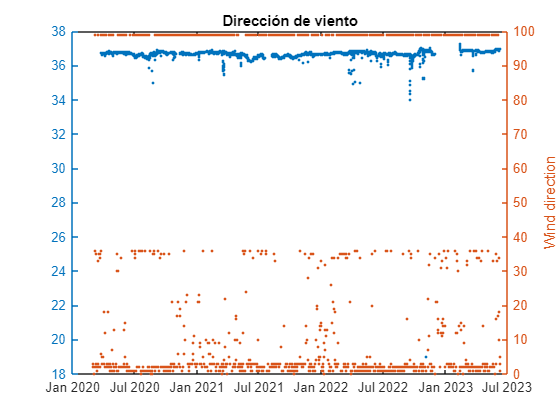

% Salinidad junto con datos de viento
yyaxis left
plot(salinidadGando.DateMicrocatSIP, salinidadGando.SSS, ".")

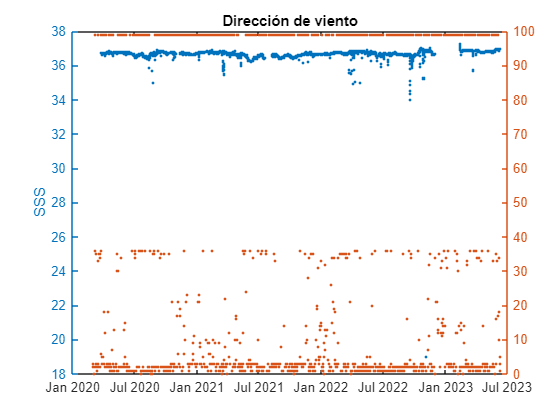

ylabel("SSS")

yyaxis right
%plot(fullTable.date(fullTable.dirWind ~= 99), fullTable.dirWind(fullTable.dirWind ~= 99), ".")
plot(fullTable.date, fullTable.dirWind, ".")

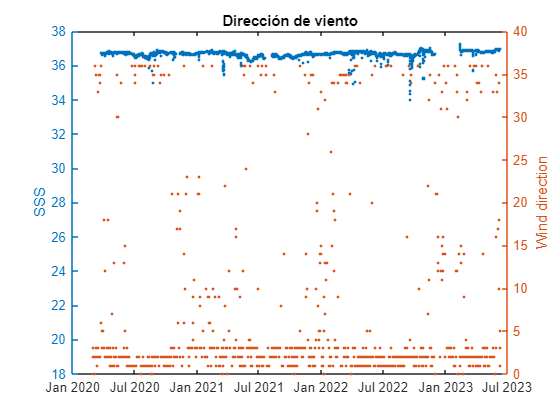

ylabel("Wind direction")
title("Dirección de viento")

## Datos de lluvia

%% Seleccionar solo los días de lluvia
rainDays = fullTable(fullTable.rain ~= 0, {'date', 'rain', 'rainYN'});

%% Especificar el formato de fecha para que se guarde bien como archivo
rainDays.date.Format = "dd/MM/uuuu";

%% Añadir una columna de 1 y 0 según si el día fue lluvioso o no o si la precipitación fue imperceptible

for i=1:numel(fullTable.rain)

    if isnan(fullTable.rain(i))
        fullTable.rainYN(i) = "Ip"; %% Precipitación imperceptible

    elseif fullTable.rain(i) == 0 
        fullTable.rainYN(i) = "0"; %% No llovió

    else
        fullTable.rainYN(i) = "1"; %% Llovió
    end
end